# Lab 4: Report 

## Witold Surdej

## Mikołaj Suchoń

clear
clc

1) Auto tuning of a PID controller using Simulink

%1st system
num1=[-3.333 0 0];
den1=[1 0 -42.51 0 0];
G1s=tf(num1,den1)

G1s =
 
    -3.333 s^2
  ---------------
  s^4 - 42.51 s^2
 
Continuous-time transfer function.



%2nd system
num2=[1 0 -32.7];
den2=[1 0 -42.51 0 0];
G2s=tf(num2,den2)

G2s =
 
    s^2 - 32.7
  ---------------
  s^4 - 42.51 s^2
 
Continuous-time transfer function.



%calling the simulink model
out = sim("simul_task1.slx");

In order to perform this task we will start by creating the simulink model, and setting all the required parameters.

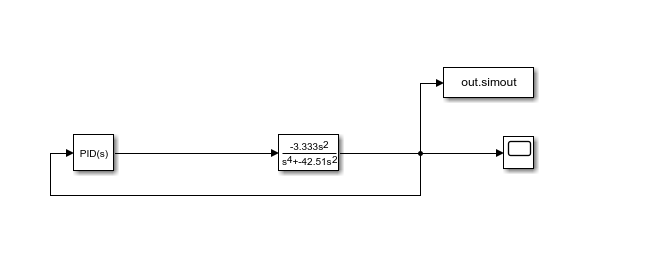

fig 1.1 - Simulink model of the system

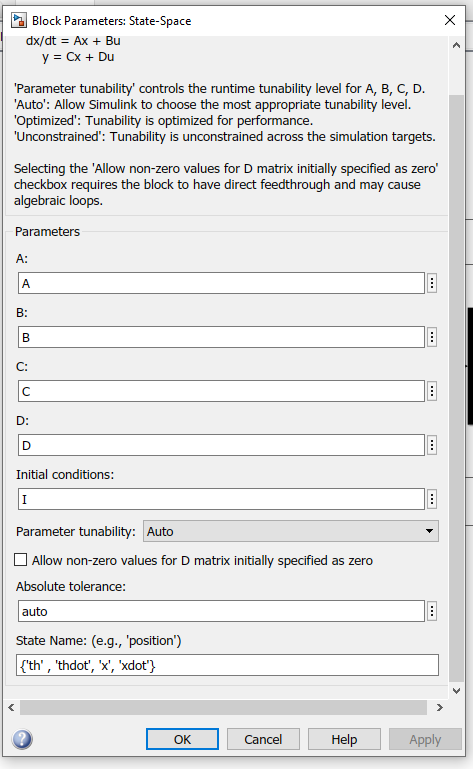

fig 1.2 - Transfer function block parameters

Now we will tune the PID controller by pressing [tune] inside the block. The process is performed 

by adjusting Response time and transient behavior of the system.

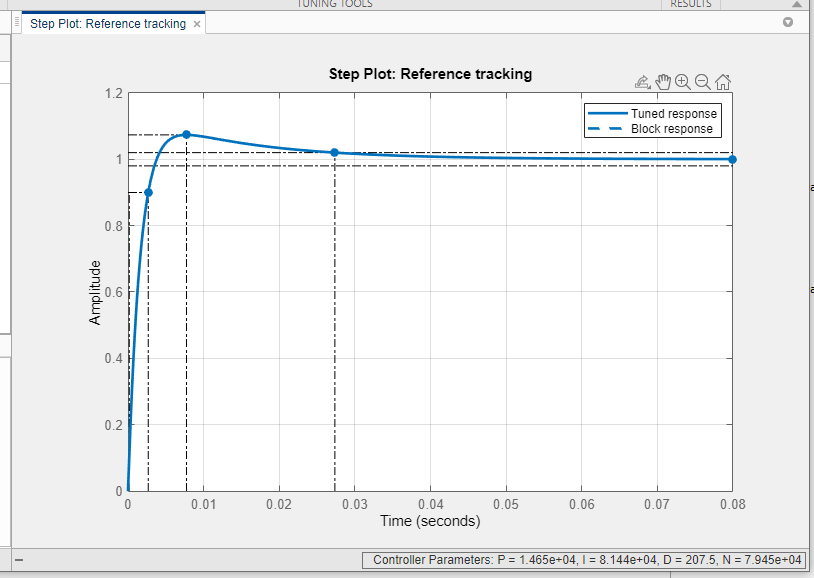

fig 1.3a - Plots obtained in PID Tuner

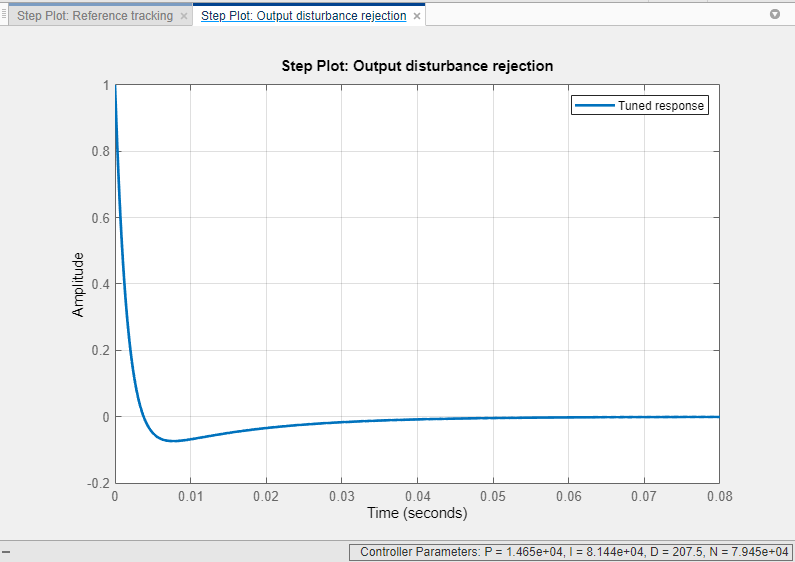

fig 1.3b - Plots obtained in PID Tuner

We have obtained the following parameters after the tuning process:

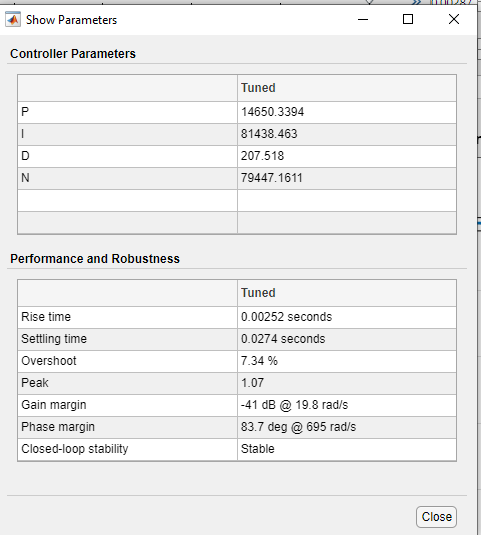

fig 1.4 - Parameters obtained in PID Tuner

Finally we can update the block and run the simulation whose results are presented below.

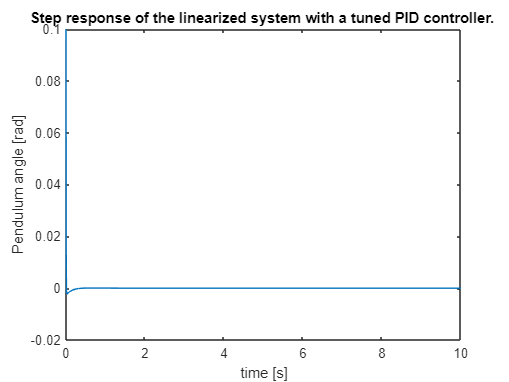

%saving data
sim_time=out.tout;
output_plot=out.simout;
save sim_time.mat
save output_plot.mat
load output_plot.mat
load sim_time.mat
%plotting results
figure()
plot(sim_time,output_plot)
title("Step response of the linearized system with a tuned PID controller. ")
xlabel("time [s]")
ylabel("Pendulum angle [rad]")

    The PID Tuner available in simulink allows us for a very quick and easy tuning process. 

The user does not require any knowladge about the actual tuning process, and his entire task

is to just adjust sliders(one for Response Time [seconds] and second for Transient Behavior) 

until the plots look proper, or even better, until the simulated parameters are all within the required 

ranges. This method allows us to significantly speed up the tuning process, but lacks the accuracy 

of the "proper" mathematical tuning.

2) Designing a state feedback controller using Simulink

This task will be performed using the results obtained in the 2nd exercises (linearized model of the 

inverted pendulum). As stated in the instruction our task will be to prepare a state feedback controller 

given a state feedback gain F.

%values for the simulink model
%State matrices found in EX.2
A=[0 1 0 0; 42.51 0 0 0; 0 0 0 1; -2.943 0 0 0];
B=[0; -3.3333; 0; 1];
C=[1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1];
D=[0; 0; 0; 0];
%Initial conditions of the system (rod angle)
I=[0.1 0 0 0];
%State feedback gain
F=[30.044 4.759 0.997 2.346];

Once again we will start by preparing a simulink model:

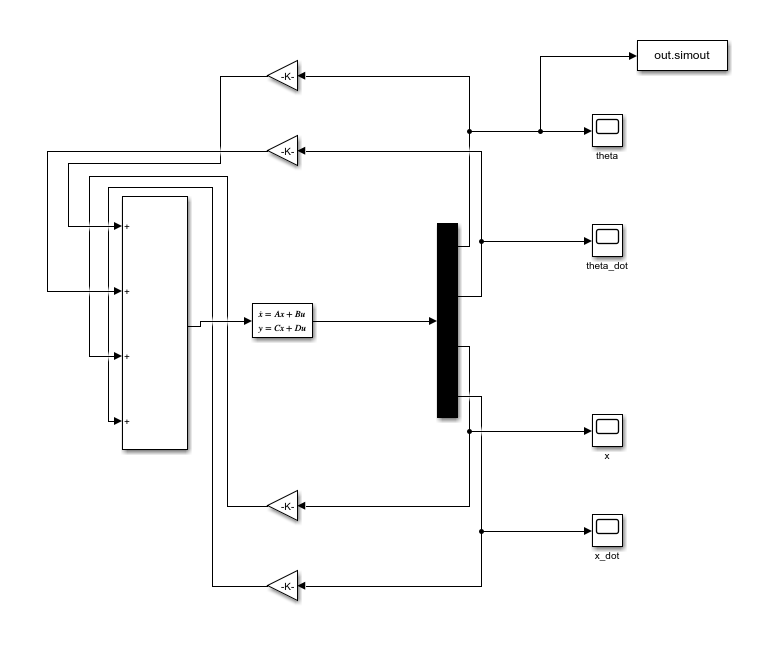

fig 2.1 - Simulink model of the system

fig 2.2 - Transfer function block parameters

Now we will run a simulation, and check the obtained results.

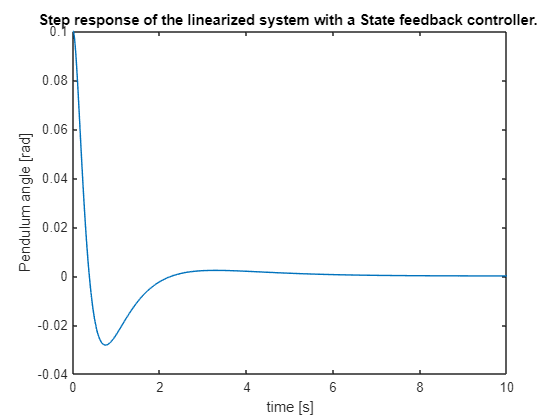

%calling the simulink model
%out = sim("simul_task2.slx");
%saving data
%sim_time2=out.tout;
%output_plot2=out.simout;
%save sim_time2.mat
%save output_plot2.mat
load output_plot2.mat
load sim_time2.mat
%plotting results
figure()
plot(sim_time2,output_plot2)
title("Step response of the linearized system with a State feedback controller. ")
xlabel("time [s]")
ylabel("Pendulum angle [rad]")

Conclusions:

Step response of the system presented above indicates that the performance of the system leaves much to

be desired. The overshoot of 28% is unsatisfactory and the response is quite slow. This method compiles

quickly but does require a lot of previous calculations.

3) Designing a Fuzzy logic controller using Fuzzy logic toolbox

The last system we will create will be controlled by a Fuzzy controller which will be designed using Fuzzy Logic Toolbox. 

Below I will present steps required for designing a Fuzzy controller.

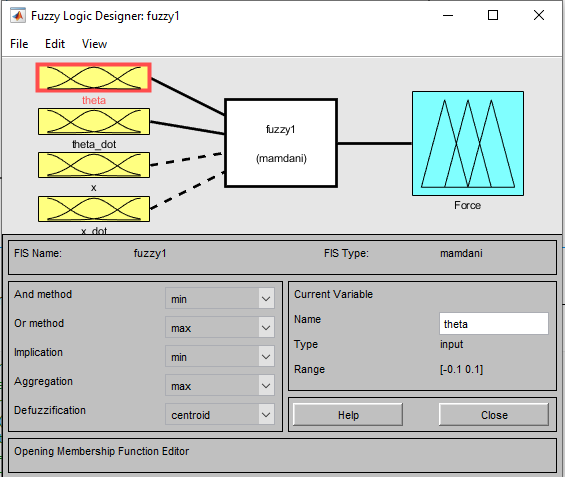

Figure 3.1 - designing the system.

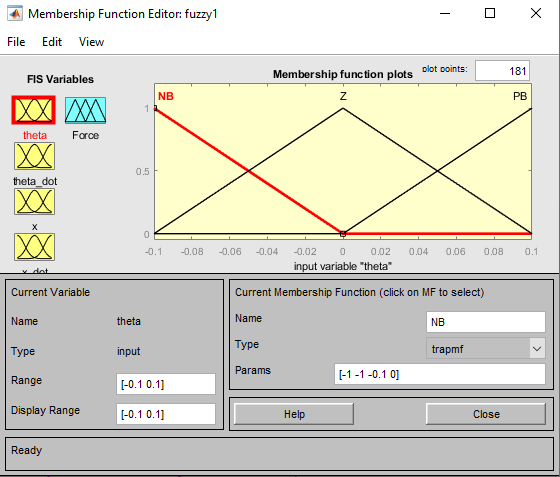

Figure 3.2a - Theta membership function.

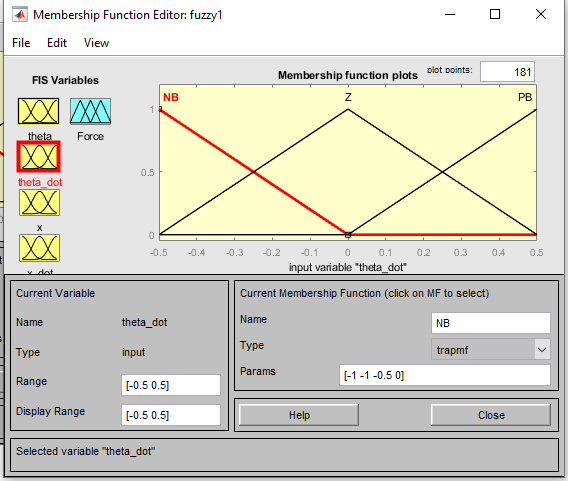

Figure 3.2b - tdot membership function.

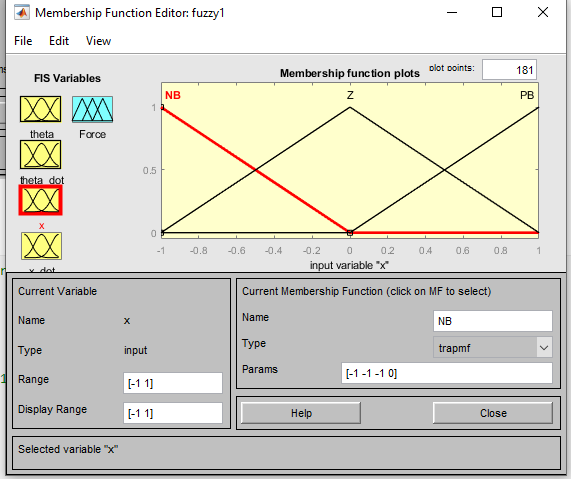

Figure 3.2c - x membership function.

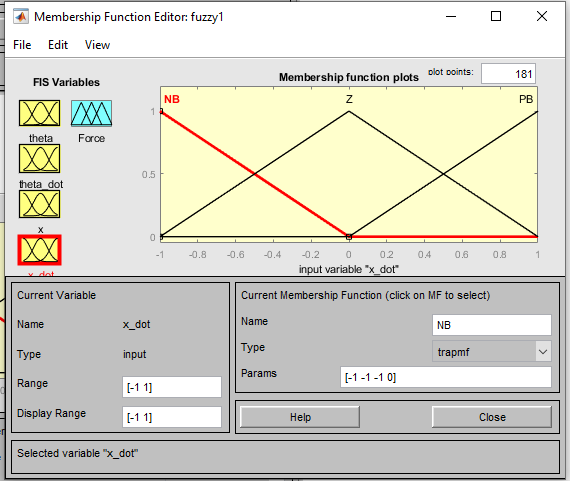

Figure 3.2d - xdot membership function.

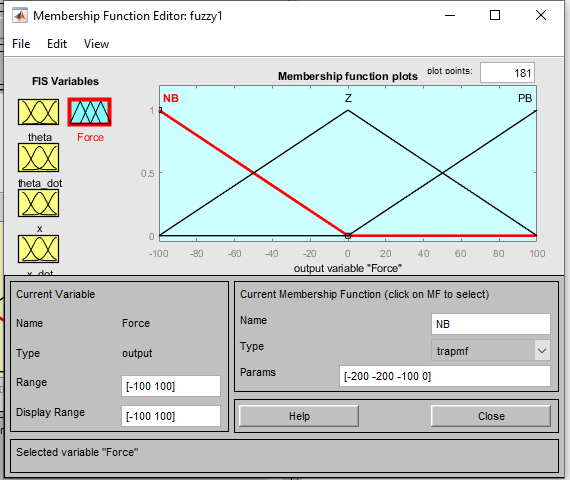

Figure 3.2e - force membership function.

After the system membership funcions are prepared we will start creating the rules of the fuzzy system:

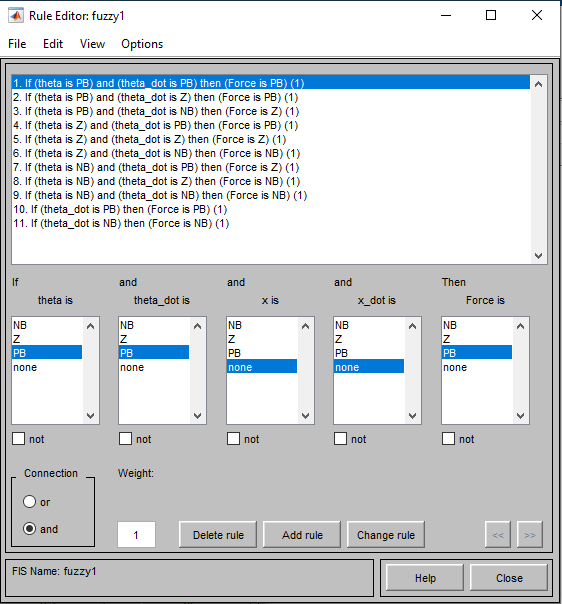

Figure 3.3 - Systems rule's

After the system is set we obtain the surface to be optimized:

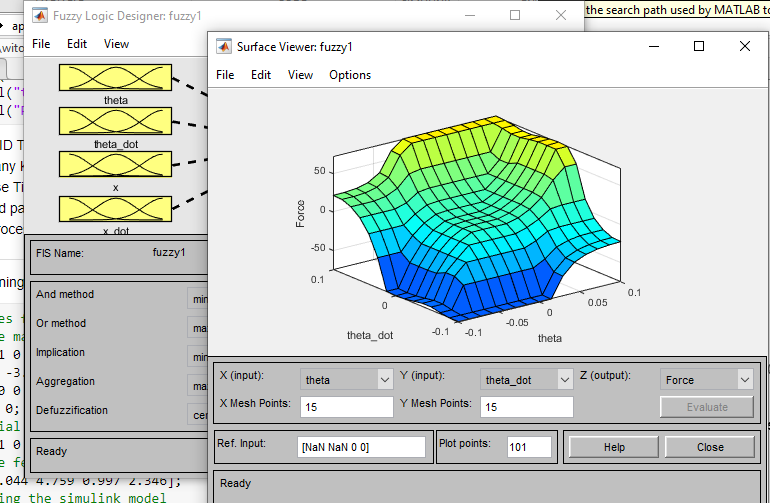

Figure 3.4 - Surface viewer, obtained surface.

Once the fuzzy controller is created we save it to a .fis file and uplod it into our simulink model:

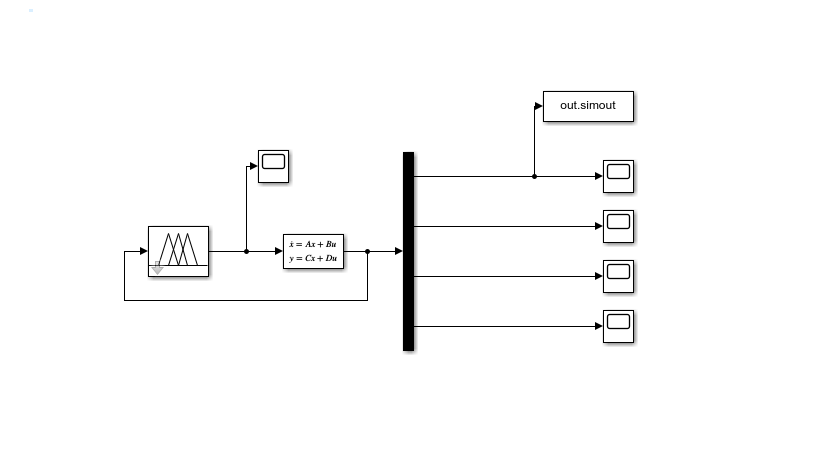

Figure 3.5 - Simulink model.

Now we can run the simulation, and obtain the desired results:

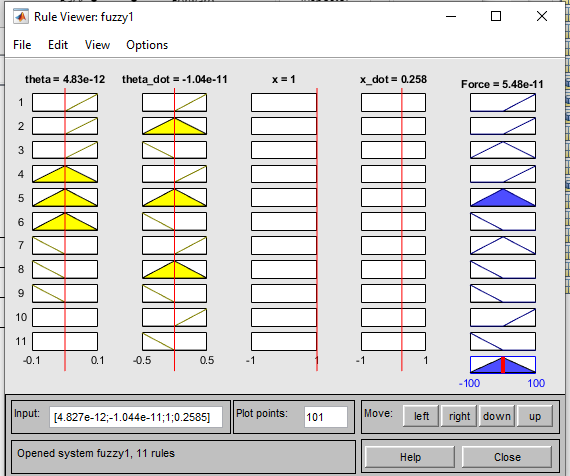

Figure 3.6 - Rule Viewer after the simulation.

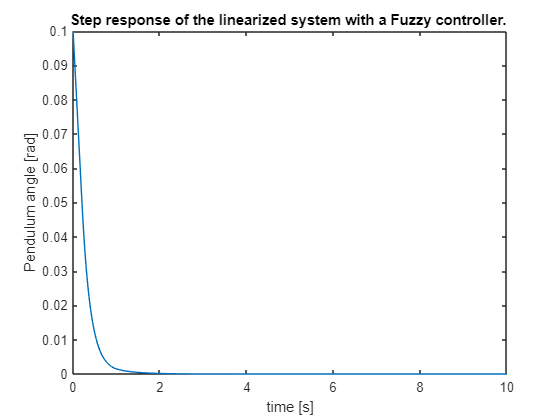

%loading prepared Fuzzy controller
%fuzzy1=readfis("fuzzy1");
%calling the simulink model
%out = sim("simul_task3.slx");
%saving data
%sim_time3=out.tout(1:1000001,:);
%output_plot3=out.simout(1:1000001,:);
%save sim_time3.mat
%save output_plot3.mat
%load output_plot3.mat
%load sim_time3.mat
%plotting results
figure()
plot(sim_time3,output_plot3)
title("Step response of the linearized system with a Fuzzy controller. ")
xlabel("time [s]")
ylabel("Pendulum angle [rad]")

Conclusions:

The fuzzy controller provides a smooth step response with no overshoot and an

acceptable settling time. The implementation is not very complicated but does require

a lot of processing power. The tunning process time for this method took was measured

in tens of minutes while both previous methods took seconds.

4) Comparing the results

Finally we can compare the 3 methodes presented above, and draw the conclusions about the 

performance of each of them.

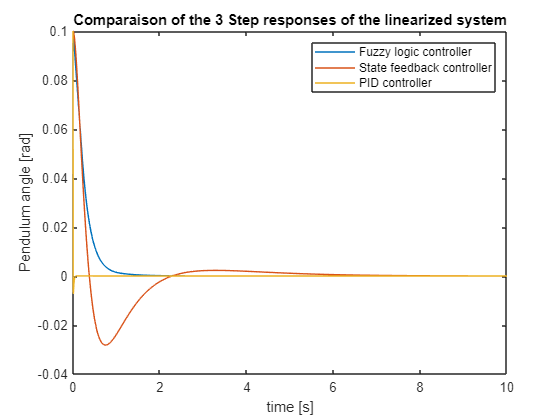

%plotting all 3 step responses on top of each other
figure()
plot(sim_time3,output_plot3), hold on
plot(sim_time2,output_plot2)
plot(sim_time,output_plot), hold off
legend("Fuzzy logic controller","State feedback controller","PID controller")
title("Comparaison of the 3 Step responses of the linearized system")
xlabel("time [s]")
ylabel("Pendulum angle [rad]")

%preparing table of results:
Fc=[1.2, 0, 0];
SSc=[1.9, 2.7 0];
PIDc=[0.25, 1, 0];
%the table presents fuzzy, state feedback and PID controllers from top to
%botton
%and from the left to right: Settling time [s], Overshoot [%] and Steady
%state error
res=[Fc;SSc;PIDc]

res =     1.2000         0         0
    1.9000    2.7000         0
    0.2500    1.0000         0


Concluisons:

    When it comes to the methodes presented above we will start by talking about two issues separately. 

Firstly we will discuss the ease of implementation of each method, and then we will refocus on the methods 

performance. Finally we will use those two indicators to conclude which and when the methods are preferable.

    Amongst the three methods presented in this report without a doubt the quickest and the easiest is the autotuning 

method within the simulink. It requires little knowladge and is very intuitive (as mantioned before). When it comes 

to the other two, without a doubt the Steady state controller takes the most time to prepare since it requires us to 

perform a lot of calculations a priori. The fuzzy logic controller takes a bit of time to set up and requires most

 theoretical knowladge to tune it properly, but in some cases it is well worth the time spent.

    Compering the performance of the three methods, it is clear that the fastest system is the one controlled by 

the PID controller and has a relativley low overshoot. The fuzzy controler, although slowest to reach desired 

value has a quicker setling time than the state feedback controller and no overshoot. The state feedback controller 

has a quite hight overshoot and takes some time to settle. 

    It is clear that for cases where a fastest response (where a resonable overshoot is allowed) the PID controller 

is the best choice both for its performance and its ease of implementation in Matlab. In system where overshoot 

is undesired and an overall smoother response is required a fuzzy controller could be a great choice. The state 

feedback controller performs poorly in comparison due to its performance and ease of implementation. 